# TP 1 : Spectral characterization 

## I. Frequency filtering  

1)

img = imread('TP01I01.jpg');
figure(1);
subplot(1,3,1);
imshow(img);
img_d=double(img);


colormap(gray(256));
f_spectrum = fftshift(fft2(img));
subplot(1,3,2);
imagesc(log(abs(f_spectrum)));
axis equal;
axis off;

2)

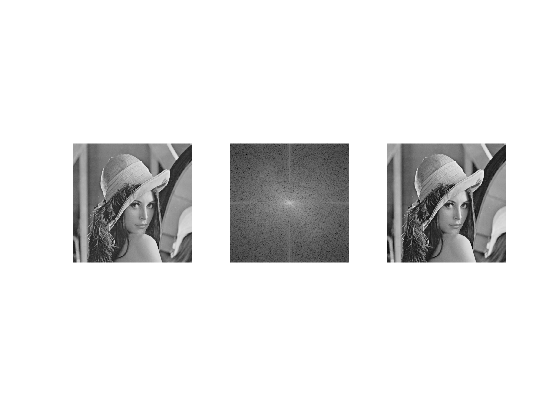

img_inv_f_spectrum= abs(ifft2(fftshift(f_spectrum)));
subplot(1,3,3);
imagesc(img_inv_f_spectrum);
axis equal;
axis off;



rmse = immse(img_d, img_inv_f_spectrum)

rmse = 2.8775e-28

3)

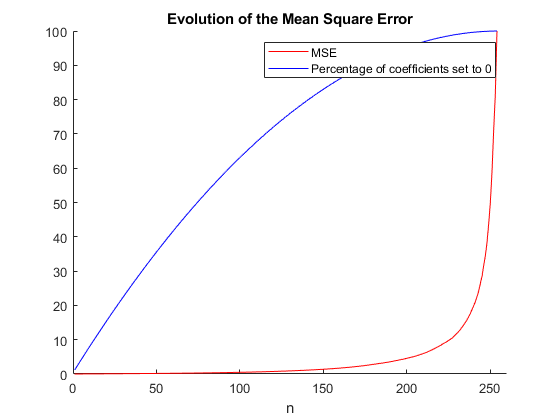

n=1;
n_tot=[];
nb_zeros=[];
nb_zero_tot=0;
error=[];
f_spectrum2=f_spectrum;
longueur_image = size(img_d,1);
largeur_image = size(img_d,2);

while (n < largeur_image/2-1)
            f_spectrum2(1:n,:)=0;
            f_spectrum2(longueur_image-n:longueur_image,:)=0;
            f_spectrum2(:,1:n)=0;
            f_spectrum2(:,largeur_image-n:largeur_image)=0;
            img_filtered = abs(ifft2(fftshift(f_spectrum2)));
            rmse = immse(img_d, img_filtered) ;
            error = [error rmse];
            nbr_zeros = length(find(f_spectrum2==0));
            nb_zeros=[nb_zeros nbr_zeros];
            n_tot=[n_tot n];
            n=n+1;
            
end
%Mise en pourcentage
max_error=max(error);
error_pct=(error/max_error)*100;
nb_zeros_pct=(nb_zeros/max(nb_zeros))*100;
figure(2);
hold on;
plot (n_tot,error_pct,'r');
plot (n_tot,nb_zeros_pct,'b');
hold off;
title("Evolution of the Mean Square Error")
legend('MSE','Percentage of coefficients set to 0')
xlabel('n') 
axis([0 n+5 0 100]);

## II Characterization

1)

chemin_fic='bibimage\'

chemin_fic = 'bibimage\'

d = dir(strcat(chemin_fic,'*.jpg'));
nbimg=length(find([d.isdir]==0));

signature=zeros(nbimg,18);
for i=1:nbimg
   field = struct2cell(d(i));
   clear img;
   img=imread(strcat(chemin_fic,field{1}));
   img_conv = rgb2gray(img);
   spectre= fftshift(fft2(img_conv));
   aff_spectre=log(abs(spectre)+1);
   % pour les lignes de 1 à 50
   signature(i,1)= caracterisation (aff_spectre,1,50,1,50);
   signature(i,2)= caracterisation (aff_spectre,1,50,51,75);
   signature(i,3)= caracterisation (aff_spectre,1,50,76,100);
   signature(i,4)= caracterisation (aff_spectre,1,50,101,125);
   signature(i,5)= caracterisation (aff_spectre,1,50,126,150);
   signature(i,6)= caracterisation (aff_spectre,1,50,151,200);
   % pour les lignes de 51 à 75
   signature(i,7)= caracterisation (aff_spectre,51,75,1,50);
   signature(i,8)= caracterisation (aff_spectre,51,75,51,75);
   signature(i,9)= caracterisation (aff_spectre,51,75,76,100);
   signature(i,10)= caracterisation (aff_spectre,51,75,101,125);
   signature(i,11)= caracterisation (aff_spectre,51,75,126,150);
   signature(i,12)= caracterisation (aff_spectre,51,75,151,200);
   % pour les lignes de 76 à 100
   signature(i,13)= caracterisation (aff_spectre,51,75,1,50);
   signature(i,14)= caracterisation (aff_spectre,51,75,51,75);
   signature(i,15)= caracterisation (aff_spectre,51,75,76,100);
   signature(i,16)= caracterisation (aff_spectre,51,75,101,125);
   signature(i,17)= caracterisation (aff_spectre,51,75,126,150);
   signature(i,18)= caracterisation (aff_spectre,51,75,151,200);
end

%Similarité de toutes les images :
for num_im= 1 : nbimg
    [m ,i]= similaire (num_im,signature,nbimg);
    disp(['L image ' num2str(num_im) ' resemble le plus a l image ' num2str(i) ]);
end

L image 1 resemble le plus a l image 32
L image 2 resemble le plus a l image 42
L image 3 resemble le plus a l image 48
L image 4 resemble le plus a l image 13
L image 5 resemble le plus a l image 6
L image 6 resemble le plus a l image 5
L image 7 resemble le plus a l image 33
L image 8 resemble le plus a l image 9
L image 9 resemble le plus a l image 8
L image 10 resemble le plus a l image 36
L image 11 resemble le plus a l image 42
L image 12 resemble le plus a l image 26
L image 13 resemble le plus a l image 4
L image 14 resemble le plus a l image 43
L image 15 resemble le plus a l image 35
L image 16 resemble le plus a l image 45
L image 17 resemble le plus a l image 37
L image 18 resemble le plus a l image 36
L image 19 resemble le plus a l image 30
L image 20 resemble le plus a l image 17
L image 21 resemble le plus a l image 41
L image 22 resemble le plus a l image 42
L image 23 resemble le plus a l image 24
L image 24 resemble le plus a l image 23
L image 25 resemble le plus a 